# EXPERIMENTS

clear;
creditrating = readtable('CreditRating_Historical.dat');

data = table2array(creditrating(:,2:end-1)); labels = table2array(creditrating(:,end));

% Convert to ratings to numeric values

Y = zeros(length(labels), 1);
for i = 1:length(labels)
    rating = labels{i};
    switch rating
        case 'AAA'
            Y(i) = 1;
        case 'AA'
            Y(i) = 2;
        case 'A'
            Y(i) = 3;
        case 'BBB'
            Y(i) = 4;
        case 'BB'
            Y(i) = 5;
        case 'B'
            Y(i) = 6;
        case 'CCC'
            Y(i) = 7;
    end
end

% Pick out two classes to perform binary SVM
ind1 = 4; ind2 = 5;
indices = sort([find(Y==ind1); find(Y==ind2)]); n = length(indices);
X = zeros(n, 6); y = zeros(n,1); 
for i = 1:n
    index = indices(i);
    X(i,:) = data(index,:);
    if(Y(index) == ind1)
        y(i) = -1;
    elseif(Y(index) == ind2)
        y(i) = 1;
    end
end
X = X./(max(abs(X)));

% Reduced dataset size for fast testing.
numTrain = 400;
idx = randperm(n);
ytrain = y(idx(1:numTrain)); Xtrain = X(idx(1:numTrain),:);
ytest = y(idx(numTrain:end)); Xtest = X(idx(numTrain:end),:);

SAVE = false;

addpath(['src'])

## SMO Experiment 1 - Convergence Rates of Poly + Gaussian Kernels

eps = 1e-2; tol = 1e-2; maxIter = 1000; verbose = 2;
[~, ~, info_smo1, ~] = SMO(Xtrain, ytrain, 10, 'poly', 2, eps, tol, maxIter, verbose, []);
[~, ~, info_smo2, ~] = SMO(Xtrain, ytrain, 100, 'gaussian', 0.5, eps, tol, maxIter, verbose, []);

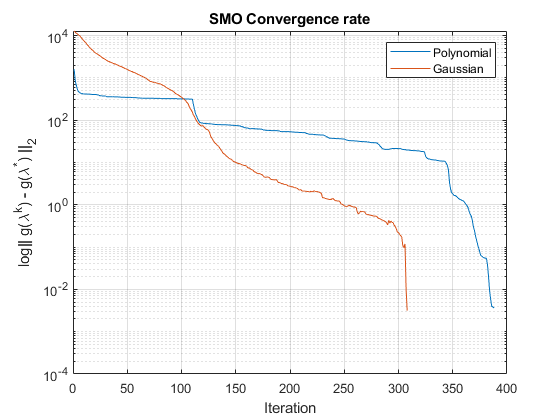

figure(2); semilogy(abs(info_smo1.objEnergy - info_smo1.objEnergy(end)));
hold on; semilogy(abs(info_smo2.objEnergy - info_smo2.objEnergy(end)));
hold off; grid on;
legend('Polynomial', 'Gaussian');
title('SMO Convergence rate'); xlabel('Iteration'); ylabel('log|| g(\lambda^k) - g(\lambda^*) ||_2');


if SAVE
    saveas(2, './images/objectiveValuesC1_5.png');
end

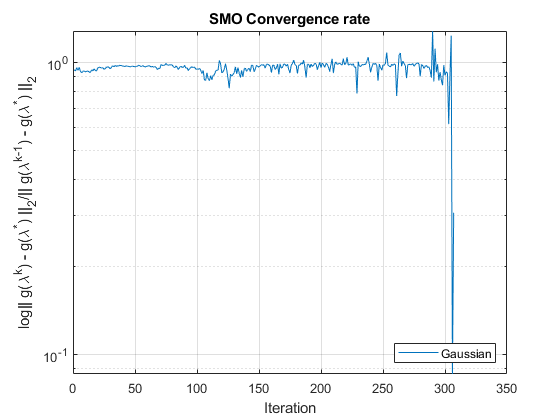

figure(2); semilogy(abs(info_smo2.objEnergy(2:end-1) - info_smo2.objEnergy(end))./abs(info_smo2.objEnergy(1:end-2) - info_smo2.objEnergy(end)))
grid on;
legend('Gaussian', 'Location', 'SouthEast');
title('SMO Convergence rate'); xlabel('Iteration'); ylabel('log|| g(\lambda^k) - g(\lambda^*) ||_2/|| g(\lambda^{k-1}) - g(\lambda^*) ||_2');


if SAVE
    saveas(2, './images/objectiveValuesC1_8.png');
end

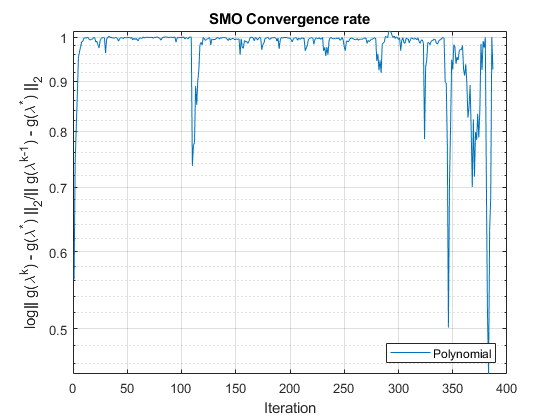

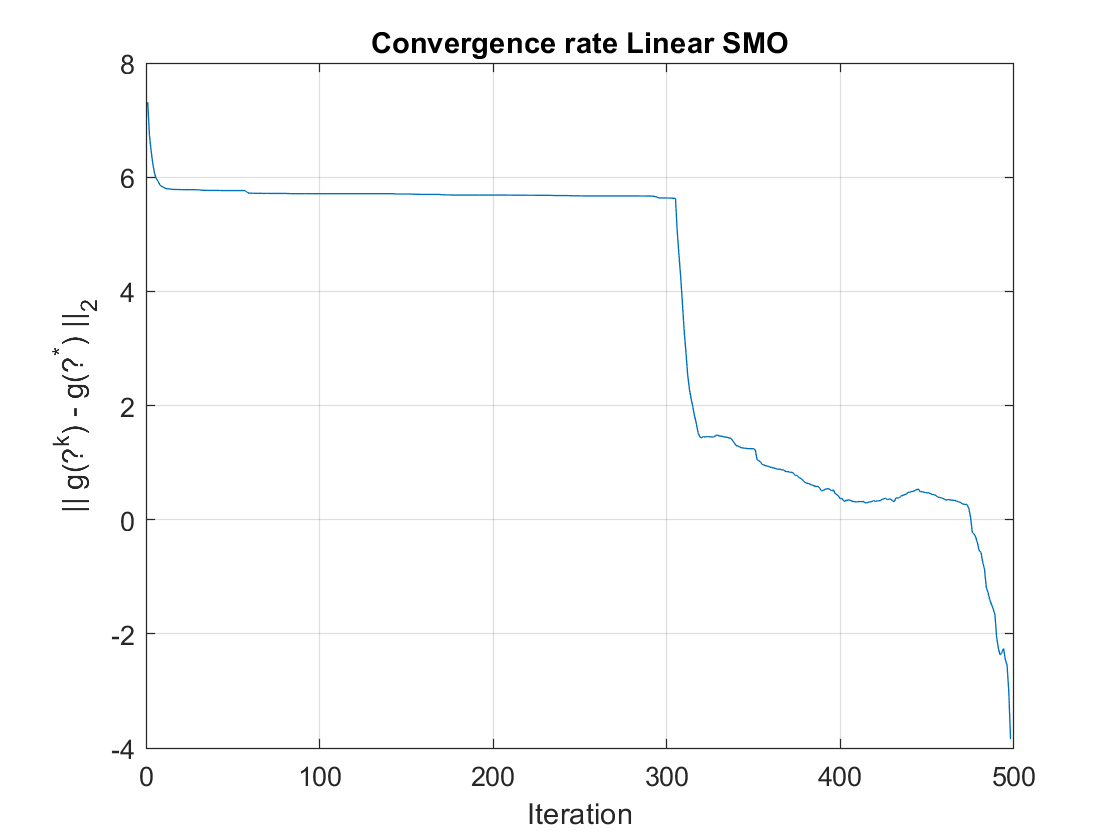

figure(3); semilogy(abs(info_smo1.objEnergy(2:end-2) - info_smo1.objEnergy(end))./abs(info_smo1.objEnergy(1:end-3) - info_smo1.objEnergy(end)))
grid on; hold off;
legend('Polynomial', 'Location', 'SouthEast');
title('SMO Convergence rate'); xlabel('Iteration'); ylabel('log|| g(\lambda^k) - g(\lambda^*) ||_2/|| g(\lambda^{k-1}) - g(\lambda^*) ||_2');

## LOG BARRIER EXPERIMENT 1 - varying mu

Range of mu's

mus = [2,10,100]; dgaps = {}; desc = {};
% Constant params
warning('off')
C = 10; t = 1; maxIter = 120; kernelType = 'poly'; kernelParam = 2; verbose = 2;
for mu = mus
    [~, ~, info_logb, ~] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, kernelParam, verbose, []);
    dgaps{end+1} = info_logb.dGap;
    desc{end+1} = compose('mu = %d', mu);
end

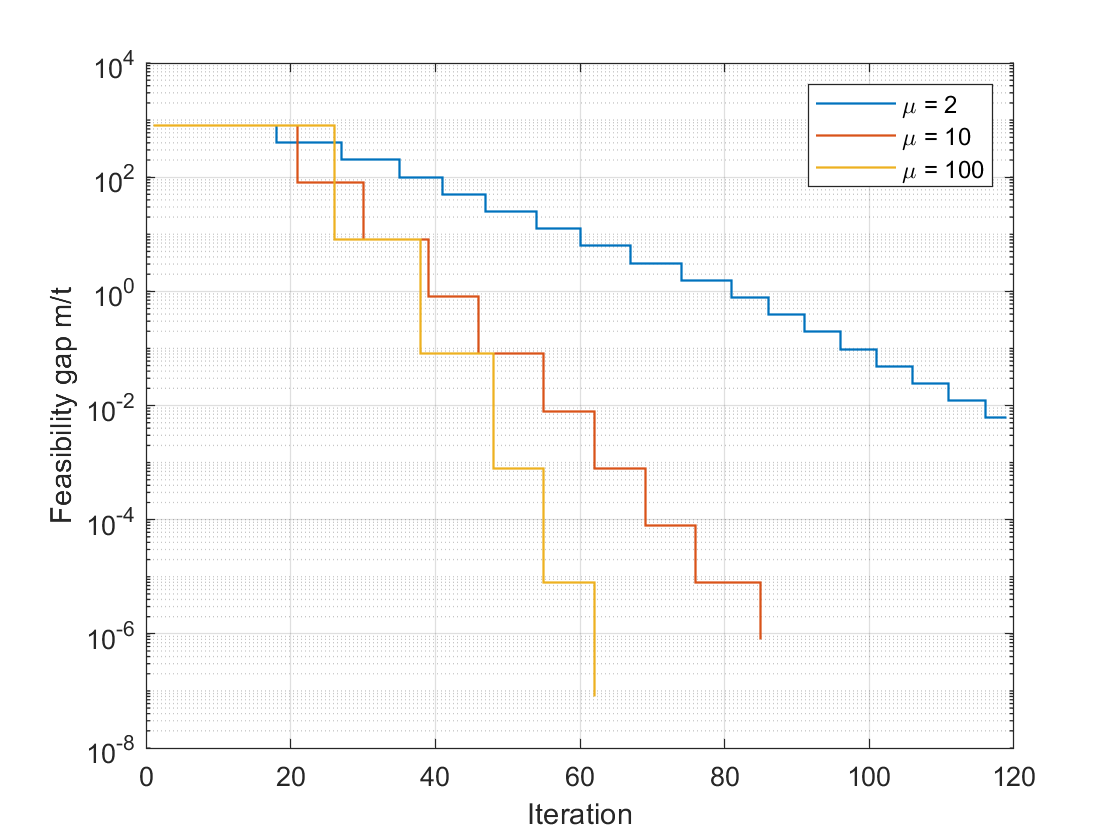

figure(1)
for i = 1:length(dgaps)
    stairs((dgaps{i}), 'LineWidth', 0.8);
    hold on
end
set(gca, 'YScale', 'log'); grid on; legend('\mu = 2', '\mu = 10', '\mu = 100')
xlabel('Iteration'); ylabel('Feasibility gap m/t');
hold off;

if SAVE
    saveas(1, './images/logFeasibilityGap_1.png');
end

## LOG BARRIER EXPERIMENT 2 - Newton Convergence

C = 20; mu = 10; t = 1; maxIter = 80; 
kernelType = 'gaussian'; kernelParam = 0.5; verbose = 2;

[ ~, ~, info_logb, ~] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, kernelParam, verbose, []);

iterates = info_logb.ns; tVal = info_logb.t; logbDiff = [];
for i = 1:(length(iterates) - 1)
    logbDiff = [logbDiff norm(iterates(i) - iterates(end))];
end

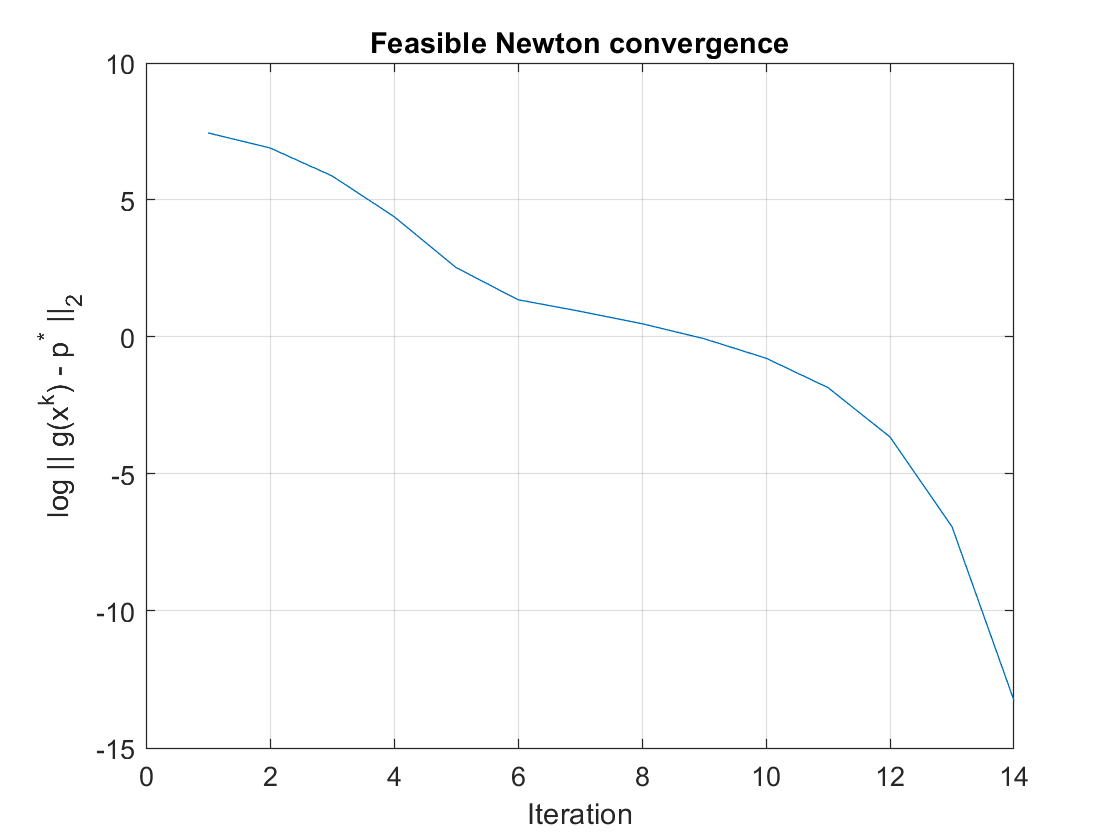

SAVE = false;
figure(5); plot(log(logbDiff)); grid on
title('Feasible Newton convergence'); xlabel('Iteration'); ylabel('log || g(x^k) - p^* ||_2');


if SAVE
    saveas(5, './images/NWconv_1.png');
end

if SAVE
    saveas(60, './images/NWconv_2.png');
end

## LOG BARRIER EXPERIMENT 3 -  OBJECTIVE FUNCTION CONVERGENCE

SAVE = false;
C = 20; mu = 5; t = 1; maxIter = 140; 
verbose = 2;
[ ~, ~, info_logb_1, ~] = logBarrier(Xtrain, ytrain, 100, mu, t, maxIter, 'gaussian', 0.5, verbose, []);
[ ~, ~, info_logb_2, ~] = logBarrier(Xtrain, ytrain, 10, mu, t, maxIter, 'poly', 2, verbose, []);
%[ ~, ~, info_logb_3, ~] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, 'linear', 1, verbose, []);

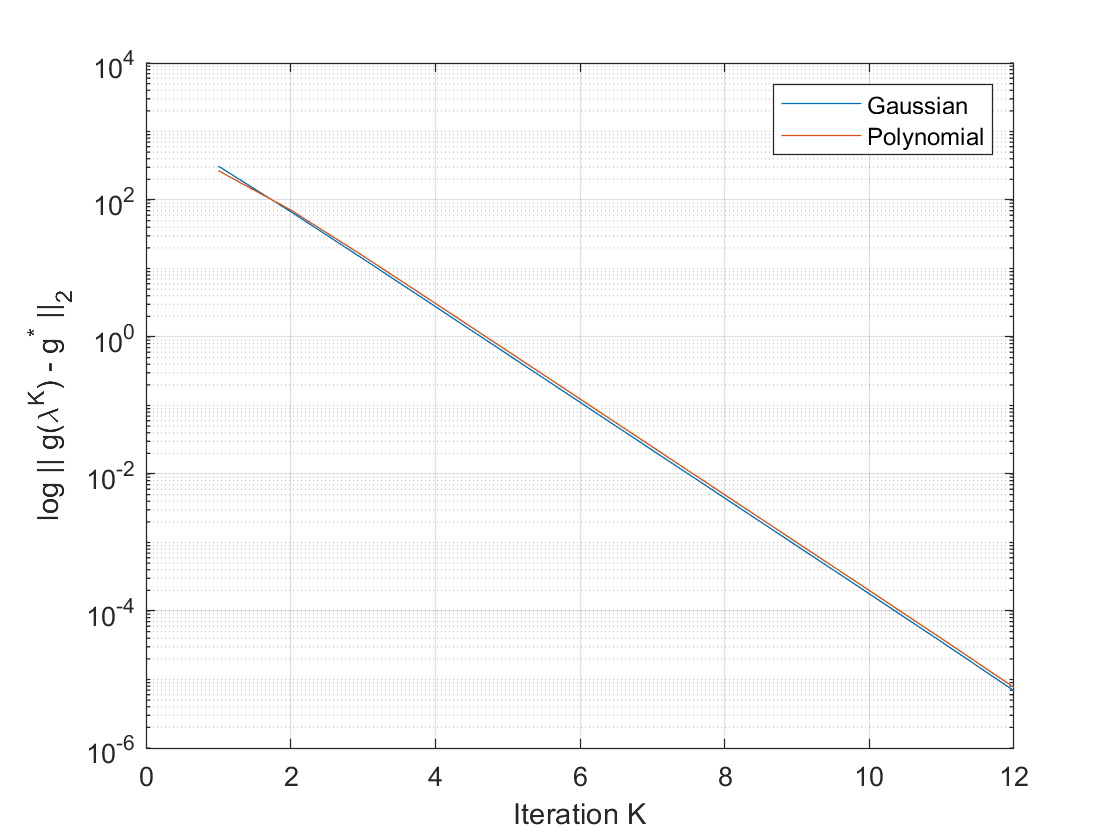

figure(30)
semilogy(abs(info_logb_1.outer(1:end-2) - info_logb_1.outer(end)))
hold on;
semilogy(abs(info_logb_2.outer(1:end-2) - info_logb_2.outer(end)))
grid on; legend('Gaussian','Polynomial');
hold off;
xlabel('Iteration K'); ylabel('log || g(\lambda^K) - g^* ||_2');

if SAVE
    saveas(30, './images/log_barrier_conv.png');
end

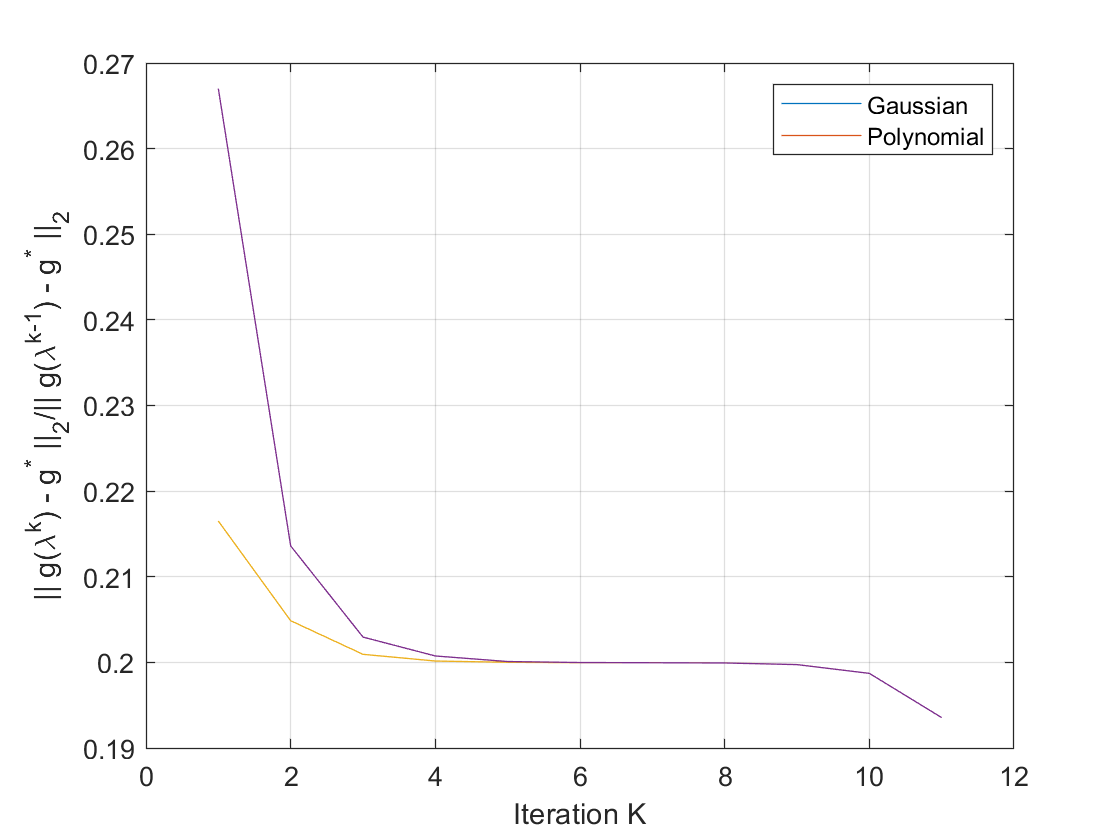

figure(30)
plot(abs(info_logb_1.outer(2:end-2) - info_logb_1.outer(end))./abs(info_logb_1.outer(1:end-3) - info_logb_1.outer(end)))
hold on;
plot(abs(info_logb_2.outer(2:end-2) - info_logb_2.outer(end))./abs(info_logb_2.outer(1:end-3) - info_logb_2.outer(end)))
grid on; legend('Gaussian','Polynomial'); hold off;
xlabel('Iteration K'); ylabel('|| g(\lambda^k) - g^* ||_2/|| g(\lambda^{k-1}) - g^* ||_2');

if SAVE
    saveas(30, './images/log_barrier_conv_1.png');
end

## EXPERIMENT 4 - PERFORMANCE of Algorithms (CPU time)

eps = 1e-4; tol = 1e-4; maxIter = 2000; C = 5; mu = 20; t = 1;
kernelType = 'poly'; kernelParam = 1; verbose = 1;
[~, ~, info_smo, ~] = SMO(Xtrain, ytrain, C, kernelType, kernelParam, eps, tol, maxIter, verbose, []);
[ ~, ~, info_logb, ~] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, kernelParam, verbose, []);

fprintf('SMO iterations: %d \n',info_smo.nIter);

SMO iterations: 931 


fprintf('SMO time: %f \n',info_smo.Time);

SMO time: 0.972679 


fprintf('SMO time/iteration: %f \n',info_smo.Time/info_smo.nIter);

SMO time/iteration: 0.001045 


fprintf('LOGB iterations: %d \n',info_logb.nIter);

LOGB iterations: 79 


fprintf('LOGB time: %f \n',info_logb.Time);

LOGB time: 2.416810 


fprintf('LOGB time/iterations: %f \n',info_logb.Time/info_logb.nIter);

LOGB time/iterations: 0.030593 


fprintf('\n');

## Experiment 5 - Value of C for Poly/Gauss

Experiment to determine optimal value of C

cVals = 10.^(-2:0.5:3); accuracyPerP = {}; accuracyPerPSMO = {};
% Define fixed parameters.
mu = 20; t = 1; maxIter = 60; kernelType = 'poly';
eps = 1e-4; tol = 1e-4; maxIterSMO = 500;
kernelParams = [1,2,3]; verbose = 1;


for p = kernelParams
    disp(p);
    accuracyPerC = [];
    accuracyPerCSMO = [];
    for C = cVals
        [a1, b1, info_logB, K1] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, p, verbose, []);
        [a2, b2, info_smo, K2] = SMO(Xtrain, ytrain, C, kernelType, p, eps, tol, maxIterSMO, verbose, []);
        accuracyPerC = [accuracyPerC info_logB.accValues];
        accuracyPerCSMO = [accuracyPerCSMO info_smo.accValues];
    end
    accuracyPerP{end+1} = accuracyPerC;
    accuracyPerPSMO{end+1} = accuracyPerCSMO;
end

     1

     2

     3



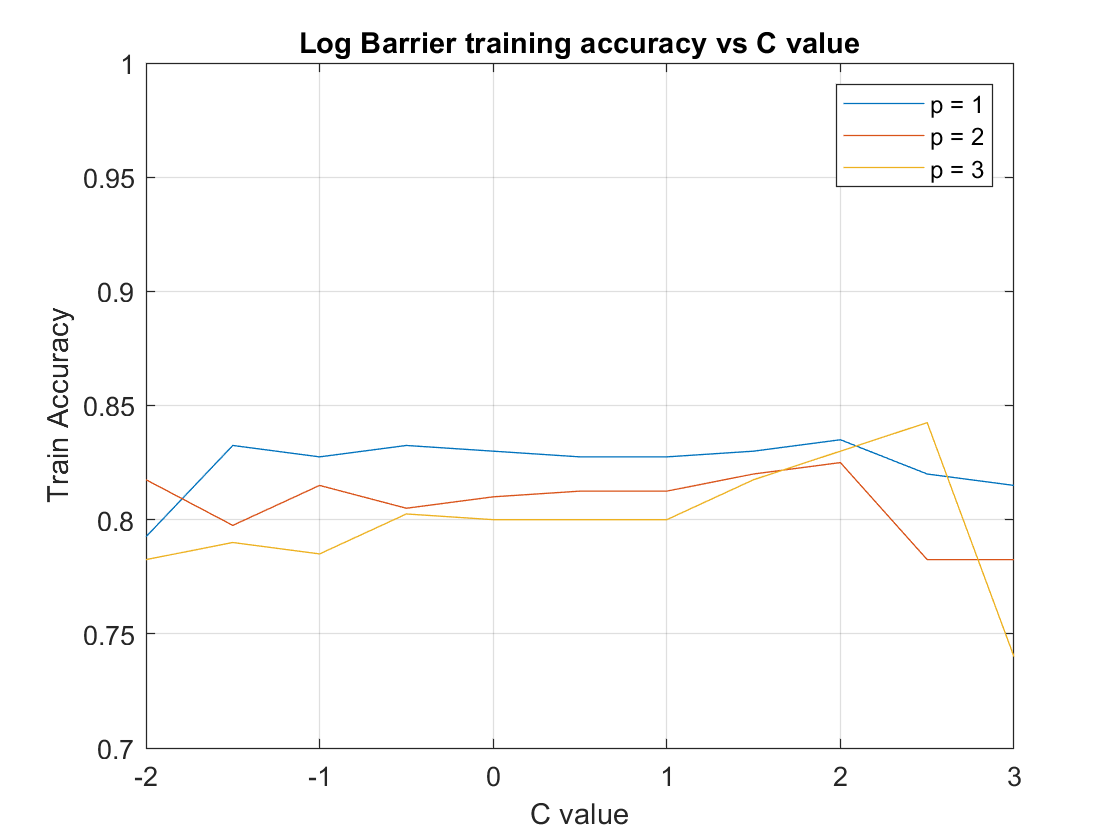

figure(7);
for i = 1:length(accuracyPerP)
    plot(log10(cVals), accuracyPerP{i});
    hold on;
end
grid on; legend('p = 1', 'p = 2', 'p = 3'); ylim([0.7,1.0]);
xlabel('C value'); ylabel('Train Accuracy'); title('Log Barrier training accuracy vs C value');
if SAVE
    saveas(7, './images/CpolyLOGB.png');
end
hold off

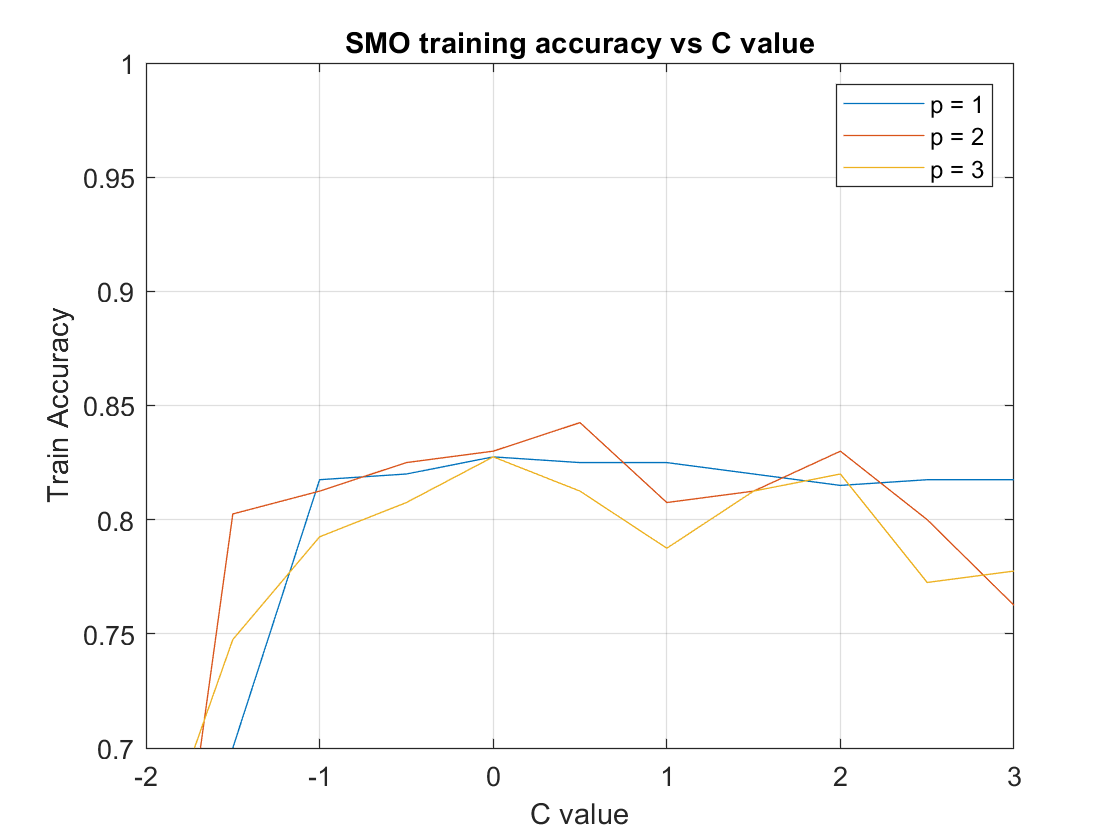


figure(8);
for i = 1:length(accuracyPerPSMO)
    plot(log10(cVals), accuracyPerPSMO{i});
    hold on;
end
grid on; legend('p = 1', 'p = 2', 'p = 3'); ylim([0.7,1.0]);
xlabel('C value'); ylabel('Train Accuracy'); title('SMO training accuracy vs C value')
if SAVE
    saveas(8, './images/CpolySMO.png');
end
hold off

## Experiment 6 - objective function/ training/ test for Poly kernel p = 1,2,3

C = 10;
mu = 10; t = 1; maxIter = 80; 
eps = 1e-4; tol = 1e-4; maxIterSMO = 4000;
kernelParams = [1,2,3]; kernelType = 'poly'; verbose = 1;

LOGB_TRA = {}; LOGB_TEA = {}; LOGB_OBJ = {};
SMO_TRA = {}; SMO_TEA = {}; SMO_OBJ = {};


for p = kernelParams
    disp(p);
    [a1, b1, info_logB, K1] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, p, verbose, []);
    [a2, b2, info_smo, K2] = SMO(Xtrain, ytrain, C, kernelType, p, eps, tol, maxIterSMO, verbose, []);
    
    ta1 = computeTestAccuracy(ytest, Xtest, ytrain, Xtrain, a1, b1, K1);
    ta2 = computeTestAccuracy(ytest, Xtest, ytrain, Xtrain, a2, -b2, K2);
    LOGB_TRA{end+1} = info_logB.accValues; LOGB_OBJ{end+1} = info_logB.objEnergy; LOGB_TEA{end+1} = ta1;
    SMO_TRA{end+1} = info_smo.accValues; SMO_OBJ{end+1} = info_smo.objEnergy; SMO_TEA{end+1} = ta2;
end

     1

     2

     3



disp(LOGB_TRA)

    [0.8275]    [0.8125]    [0.8000]



disp(LOGB_TEA)

    [0.8302]    [0.8179]    [0.7952]



disp(LOGB_OBJ)

    [-1.6383e+03]    [-1.6021e+03]    [-1.5935e+03]



disp(SMO_TRA)

    [0.8275]    [0.8300]    [0.8325]



disp(SMO_TEA)

    [0.8308]    [0.8224]    [0.8218]



disp(SMO_OBJ)

    [-1.6383e+03]    [-1.2749e+03]    [-1.3257e+03]



## Experiment 7 - Value of C for Gauss

cVals = 10.^(-2:0.5:3); accuracyPerP = {}; accuracyPerPSMO = {};
% Define fixed parameters.
mu = 20; t = 1; maxIter = 60; kernelType = 'gaussian';
eps = 1e-4; tol = 1e-4; maxIterSMO = 2000;
kernelParams = [0.01,0.1,0.5,1]; verbose = 1;

for p = kernelParams
    disp(p);
    accuracyPerC = [];
    accuracyPerCSMO = [];
    for C = cVals
        [a1, b1, info_logB, K1] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, p, verbose, []);
        [a2, b2, info_smo, K2] = SMO(Xtrain, ytrain, C, kernelType, p, eps, tol, maxIterSMO, verbose, []);
        ta1 = info_logB.accValues;
        ta2 = info_smo.accValues;
        accuracyPerC = [accuracyPerC ta1];
        accuracyPerCSMO = [accuracyPerCSMO ta2];
    end
    accuracyPerP{end+1} = accuracyPerC;
    accuracyPerPSMO{end+1} = accuracyPerCSMO;
end

    0.0100

    0.1000

    0.5000

     1



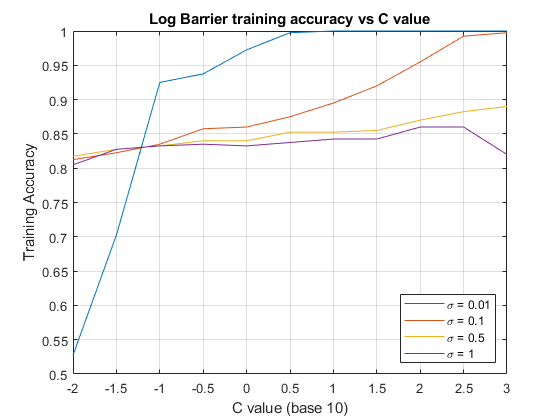

figure(9);
for i = 1:length(accuracyPerP)
    plot(log10(cVals), accuracyPerP{i});
    hold on;
end
grid on; legend('\sigma = 0.01', '\sigma = 0.1', '\sigma = 0.5', '\sigma = 1',  'Location', 'SouthEast');
xlabel('C value (base 10)'); ylabel('Training Accuracy'); title('Log Barrier training accuracy vs C value')
if SAVE
    saveas(9, './images/CgaussLOGB.png');
end
hold off

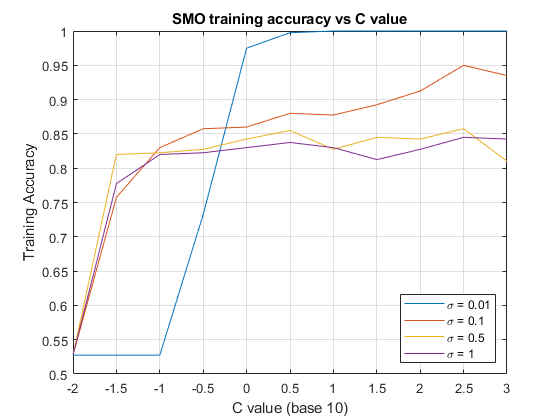


figure(10);
for i = 1:length(accuracyPerPSMO)
    plot(log10(cVals), accuracyPerPSMO{i});
    hold on;
end
grid on; legend('\sigma = 0.01', '\sigma = 0.1', '\sigma = 0.5', '\sigma = 1', 'Location', 'SouthEast');
xlabel('C value (base 10)'); ylabel('Training Accuracy'); title('SMO training accuracy vs C value')
if SAVE
    saveas(10, './images/CgaussSMO.png');
end
hold off

## Experiment 7 - objective function/ training/ test for Gauss kernel sigma = 0.01,0.5,1

C = 100;
mu = 10; t = 1; maxIter = 80; 
eps = 1e-4; tol = 1e-4; maxIterSMO = 1000;
kernelParams = [0.01,0.1,0.5,1]; kernelType = 'gaussian'; verbose = 1;

LOGB_TRA = {}; LOGB_TEA = {}; LOGB_OBJ = {};
SMO_TRA = {}; SMO_TEA = {}; SMO_OBJ = {};


for p = kernelParams
    disp(p);
    [a1, b1, info_logB, K1] = logBarrier(Xtrain, ytrain, C, mu, t, maxIter, kernelType, p, verbose, []);
    [a2, b2, info_smo, K2] = SMO(Xtrain, ytrain, C, kernelType, p, eps, tol, maxIterSMO, verbose, []);
    
    ta1 = computeTestAccuracy(ytest, Xtest, ytrain, Xtrain, a1, b1, K1);
    ta2 = computeTestAccuracy(ytest, Xtest, ytrain, Xtrain, a2, -b2, K2);
    LOGB_TRA{end+1} = info_logB.accValues; LOGB_OBJ{end+1} = info_logB.objEnergy; LOGB_TEA{end+1} = ta1;
    SMO_TRA{end+1} = info_smo.accValues; SMO_OBJ{end+1} = info_smo.objEnergy; SMO_TEA{end+1} = ta2;
end

    0.0100

    0.1000

    0.5000

     1



disp(LOGB_TRA)

    [1]    [0.9550]    [0.8700]    [0.8600]



disp(LOGB_TEA)

    [0.7563]    [0.7537]    [0.8205]    [0.8302]



disp(LOGB_OBJ)

    [-209.6307]    [-6.4606e+03]    [-1.2898e+04]    [-1.4217e+04]



disp(SMO_TRA)

    [1]    [0.9000]    [0.8500]    [0.8425]



disp(SMO_TEA)

    [0.7544]    [0.6935]    [0.8056]    [0.8283]



disp(SMO_OBJ)

    [-209.6211]    [-5.0354e+03]    [-9.9324e+03]    [-9.1643e+03]

